## Part 1:

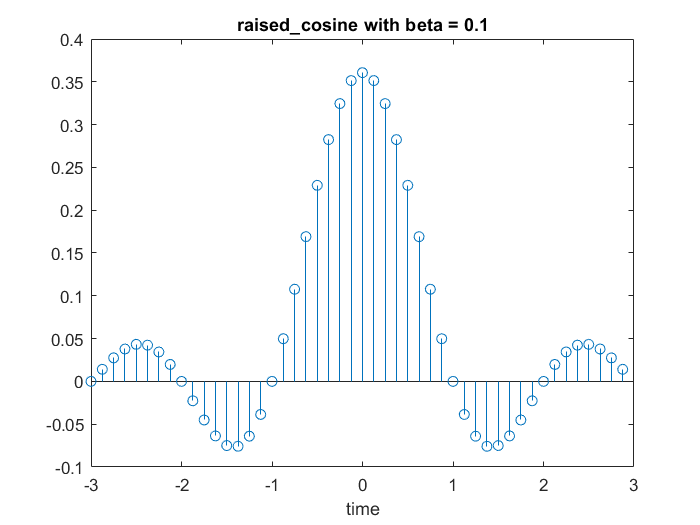

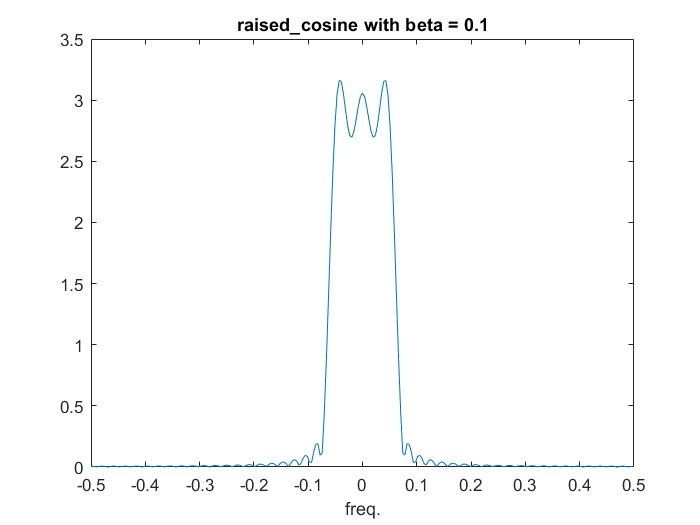

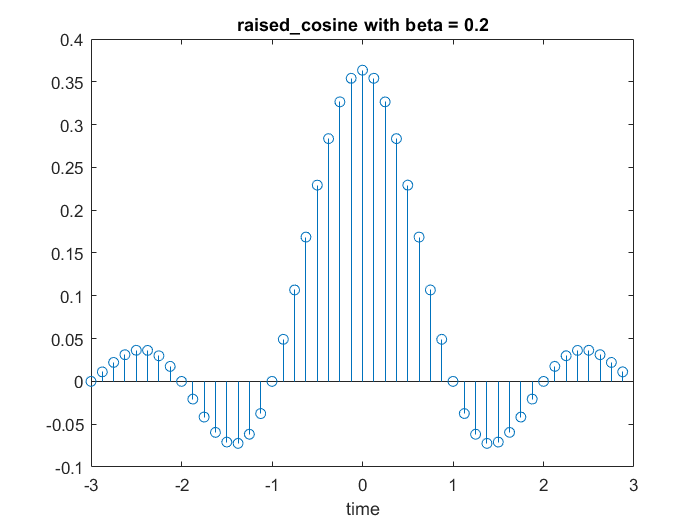

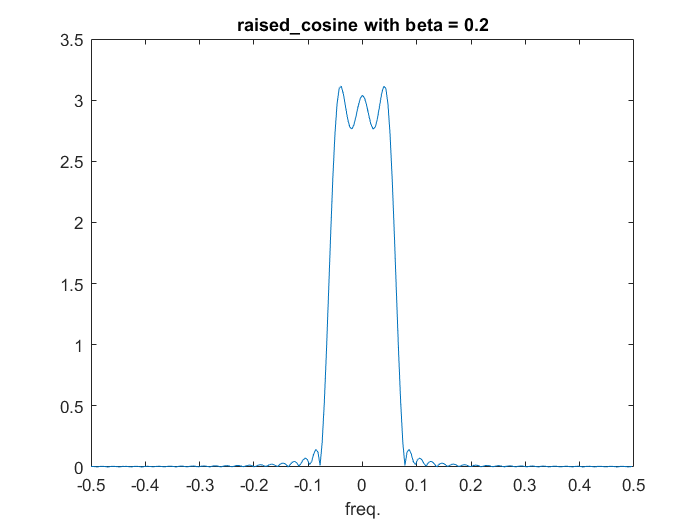

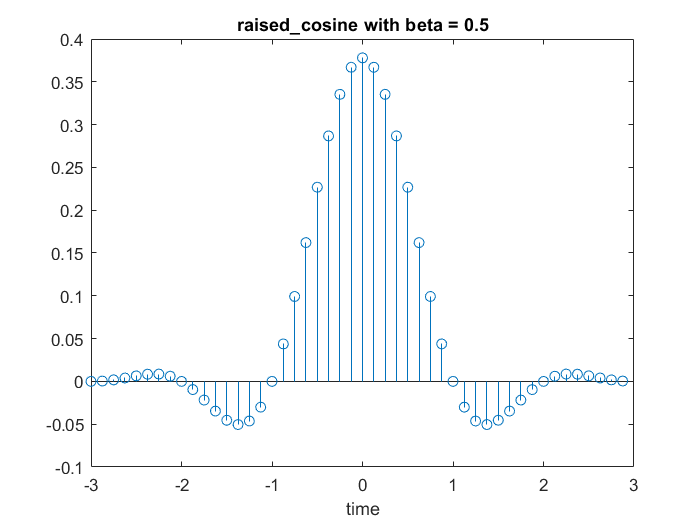

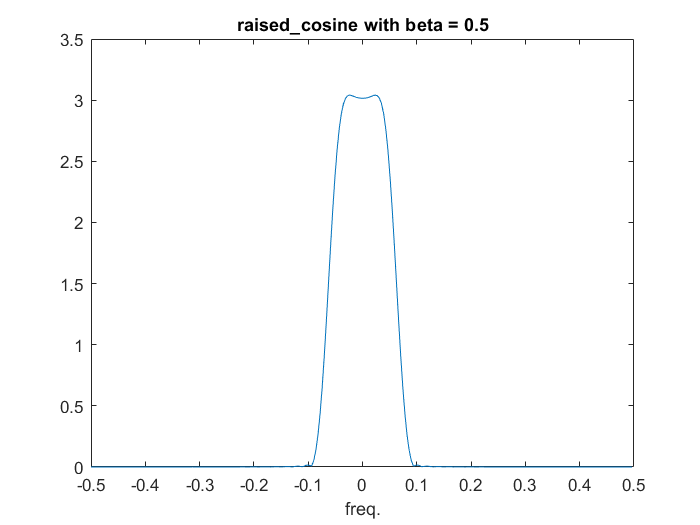

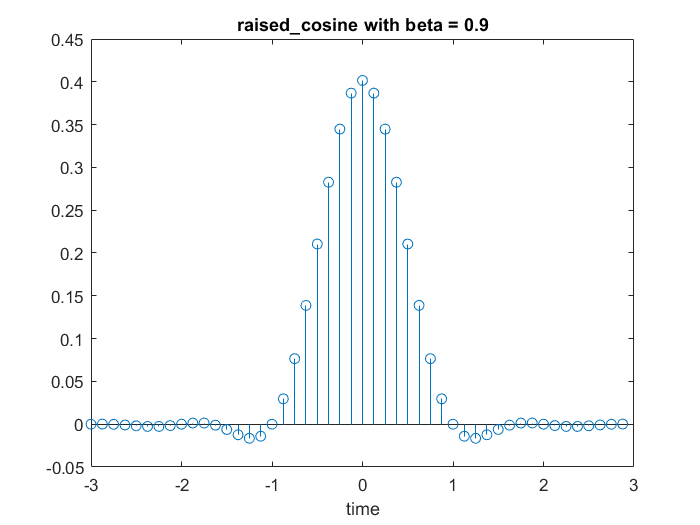

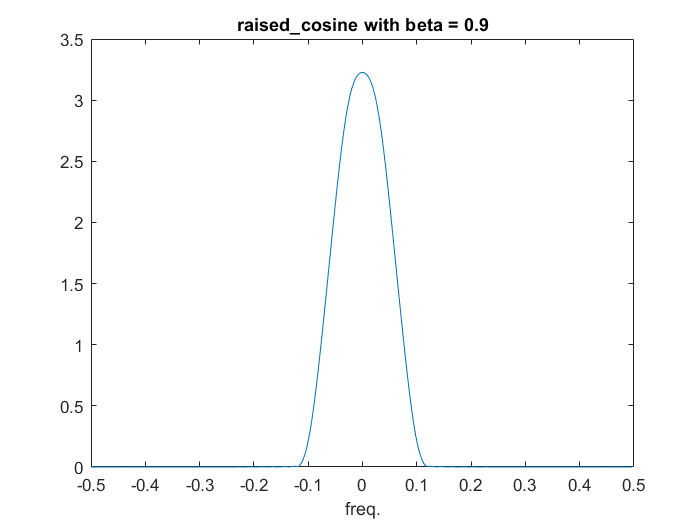

fs = 1;
smpl_per_symbl = 8;
span_in_symbl = 6;
beta = [0.1 0.2 0.5 0.9 1];
for c = 1:length(beta)
    pulse_shape('raised_cosine', fs, smpl_per_symbl, span_in_symbl, beta(c));
end

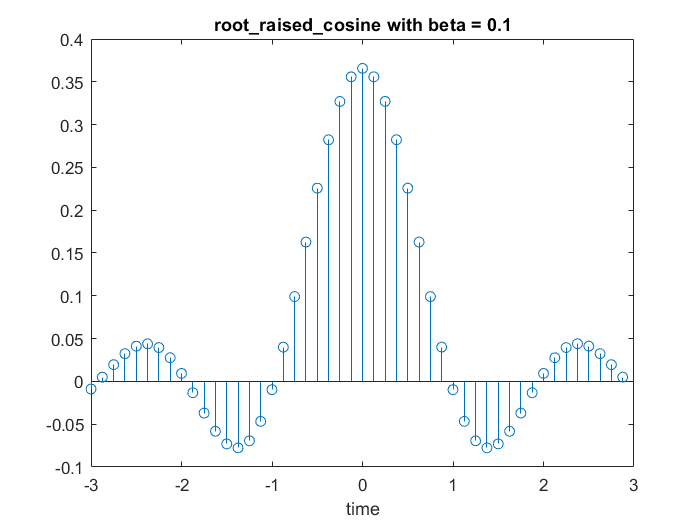

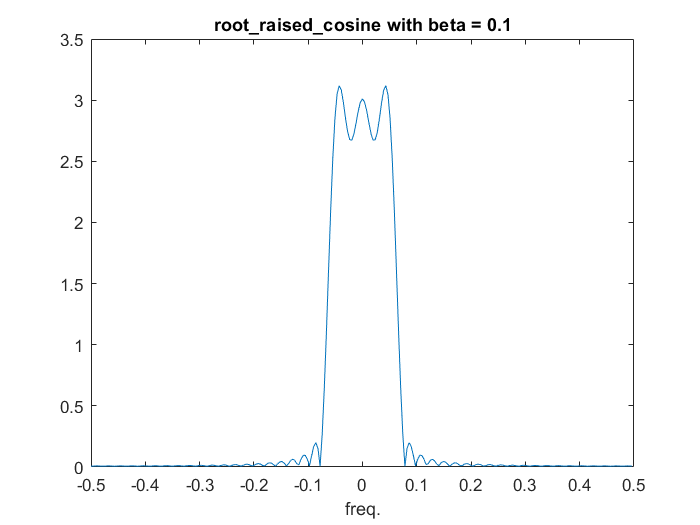

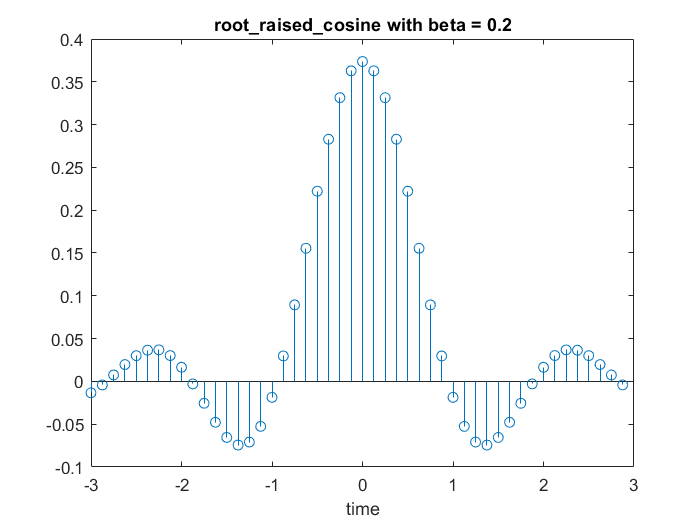

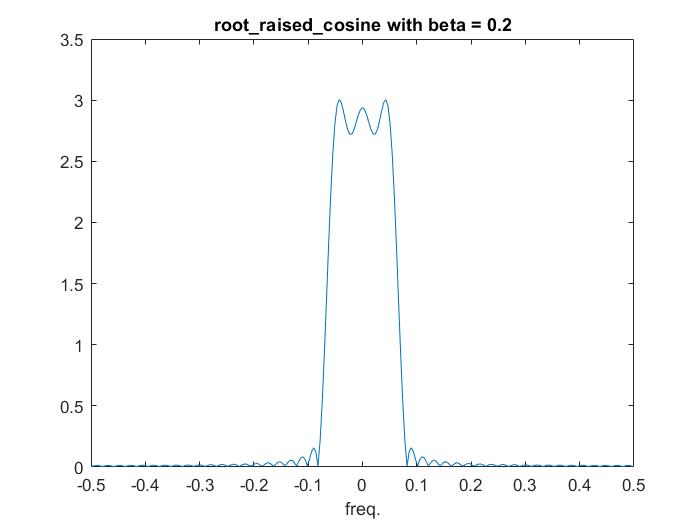

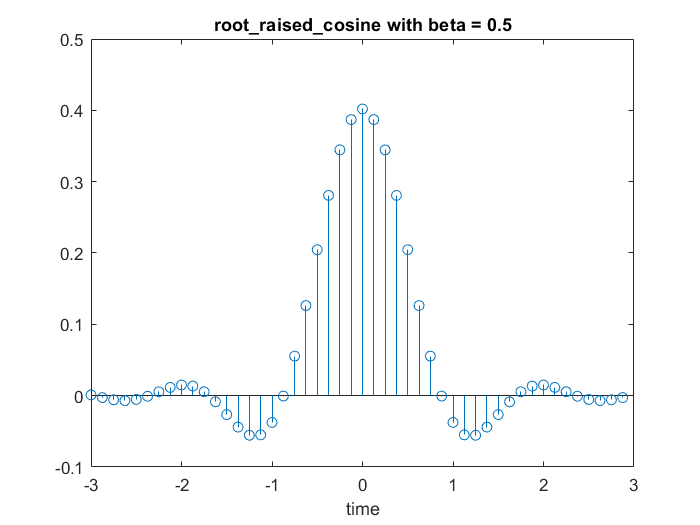

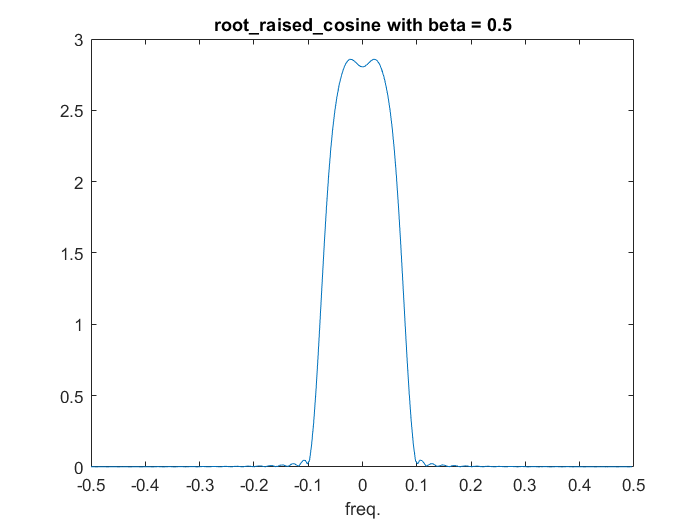

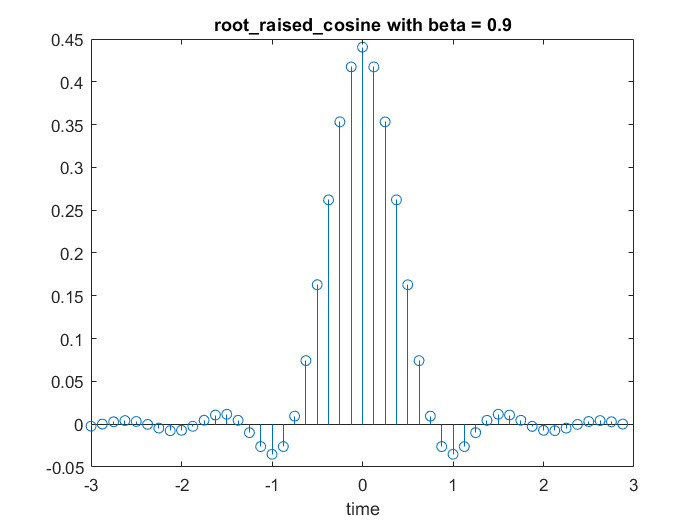

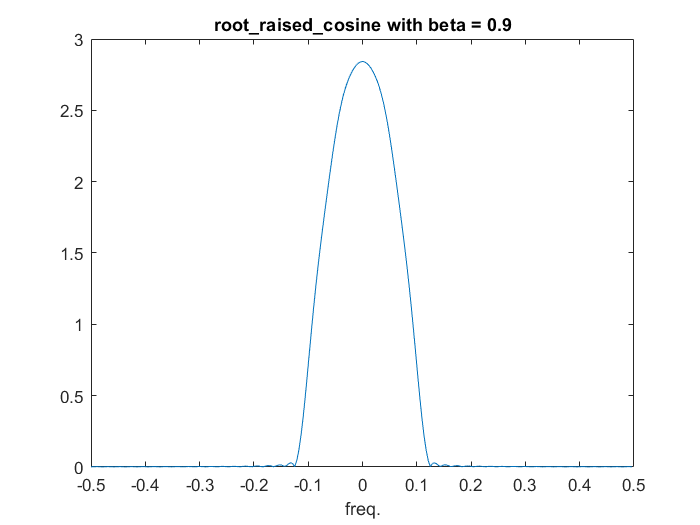

for c = 1:length(beta)
    pulse_shape('root_raised_cosine', fs, smpl_per_symbl, span_in_symbl, beta(c));
end

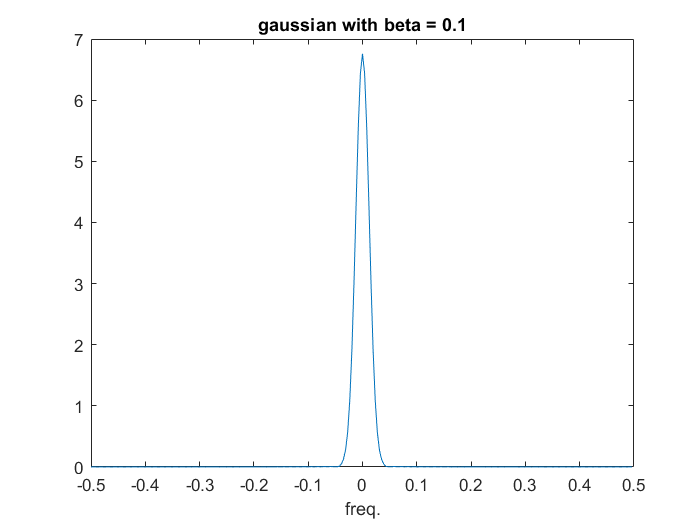

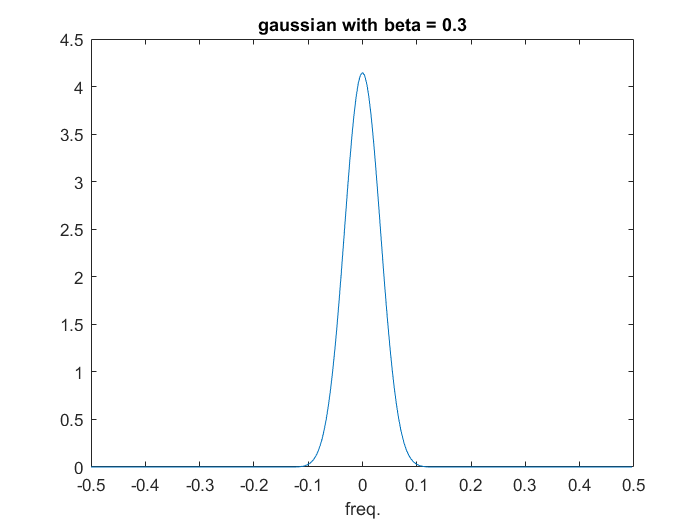

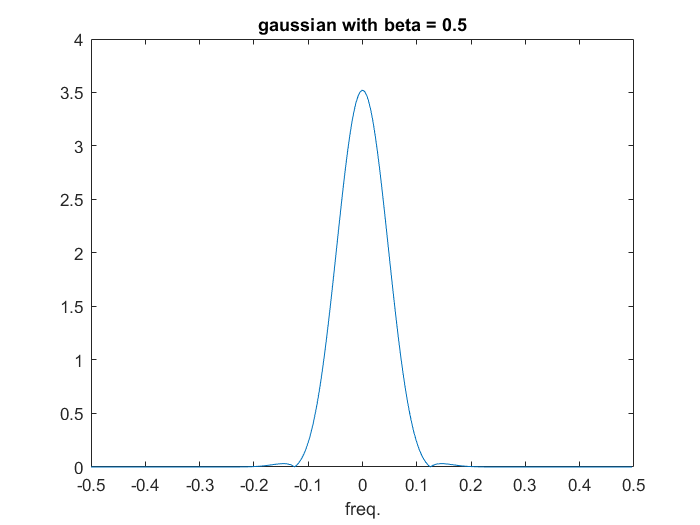

beta = [0.1 0.3 0.5];
span_in_symbl = 10;
for c = 1:length(beta)
    pulse_shape('gaussian', fs, smpl_per_symbl, span_in_symbl, beta(c));
end

#### We can see that as beta*T increases the frequency response will spread over frequency axis. 

## Part 2:

### 2.

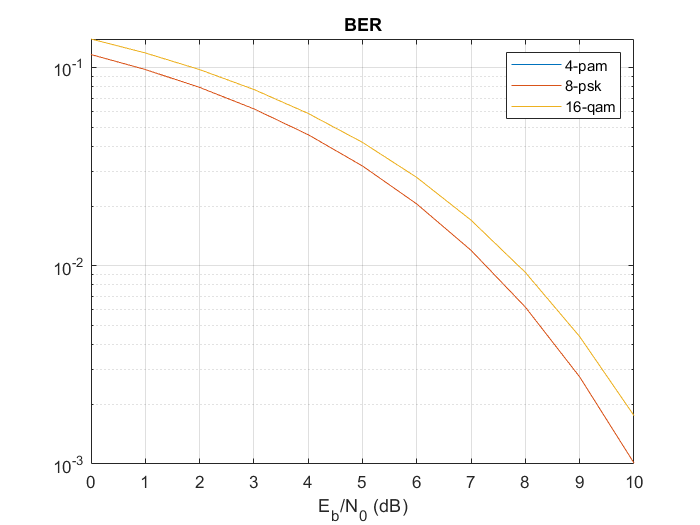

[~, p1] = plot_ER('pam', 4, 0);
[~, p2] = plot_ER('psk', 8, 0);
[c, p3] = plot_ER('qam', 16, 0);
figure
semilogy(c, p1)
hold on
semilogy(c, p2)
hold on
semilogy(c, p3)
hold off
legend('4-pam', '8-psk', '16-qam')
xlabel('E_b/N_0 (dB)')
title('BER')
grid

### 3.

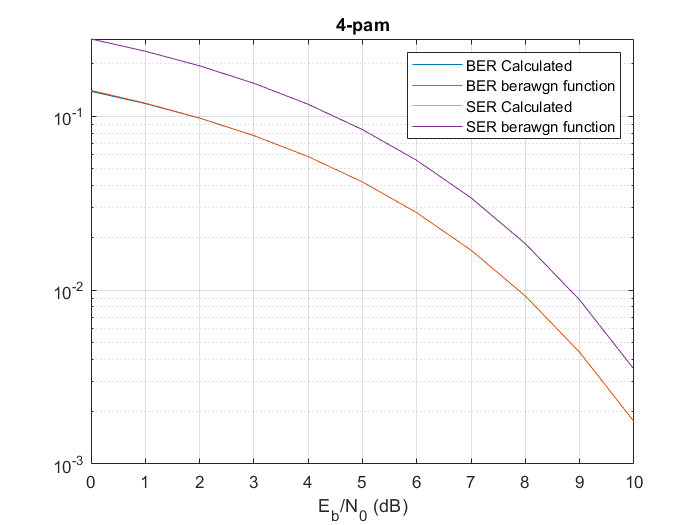

plot_ER('pam', 4, 1);

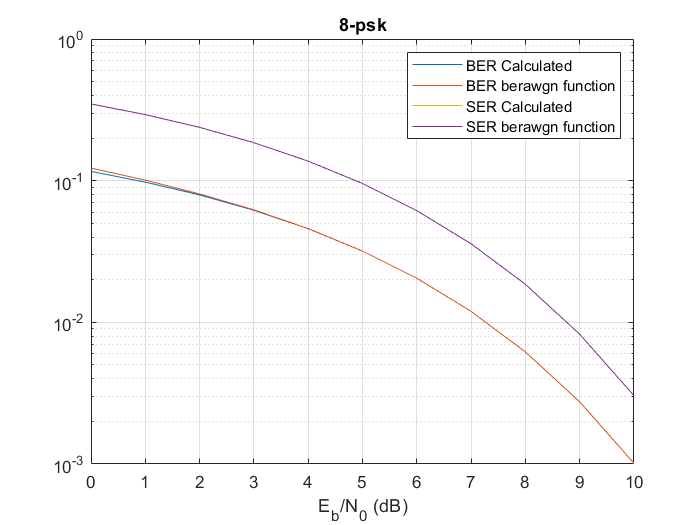

plot_ER('psk', 8, 1);

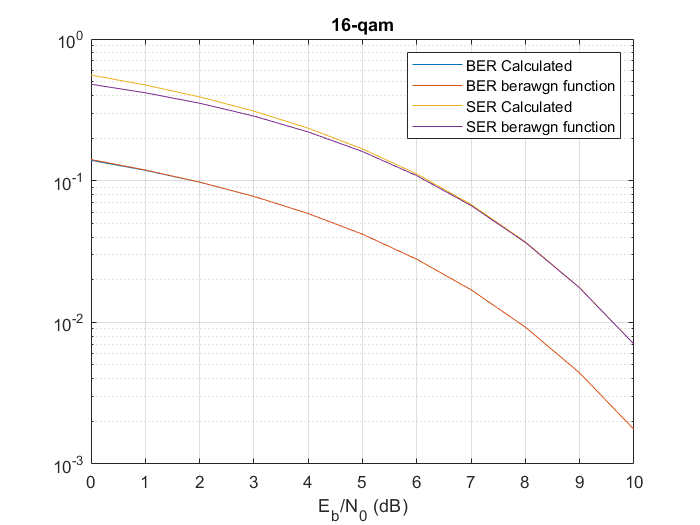

plot_ER('qam', 16, 1);

#### As shown in plots, calculated BERs are accurate.

## Functions Definition:

### part 1:

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
span_in_symbl = varargin{1};
beta = varargin{2};
t = -span_in_symbl/(2*fs):1/(fs*smpl_per_symbl):span_in_symbl/(2*fs)-1/(fs*smpl_per_symbl);
if strcmp('raised_cosine', pulse_name)
    p = sinc(t*fs) .* cos(pi*beta*t*fs) ./ (1 - (2*beta*t*fs).^2);
    idx = t == 1/(2*fs*beta) | t == -1/(2*fs*beta);
    p(idx) = pi/4 * sinc(1/(2*beta));
elseif strcmp('root_raised_cosine', pulse_name)
    p = sqrt(fs) * (sin(pi*t*fs*(1-beta)) + 4*beta*fs*t.*cos(pi*t*fs*(1+beta))) ./ (pi*fs*t.*(1-(4*beta*fs*t).^2));
    p(t == 0) = sqrt(fs) * (1 - beta + 4*beta/pi);
    idx = t == 1/(4*fs*beta) | t == -1/(4*fs*beta);
    p(idx) = beta * sqrt(fs/2) * ((1 + 2/pi) * sin(pi/(4*beta)) + (1 - 2/pi) * cos(pi/(4*beta)));
elseif strcmp('gaussian', pulse_name)
    p = (qfunc(2*pi*beta*(t - 1/(2*fs))) - qfunc(2*pi*beta*(t + 1/(2*fs)))) / log(2);
end
E = sum(p.^2);
p = p / sqrt(E);
plot_(p, t, pulse_name, fs, beta);
end

function [] = plot_(y, x, pulse_name, fs, beta)
if ~(strcmp('gaussian', pulse_name))
    figure
    stem(x, y)
    xlabel('time')
    title([pulse_name, ' with beta = ', num2str(beta)], 'Interpreter', 'none')
end
Yf = fftshift(fft(y, 256));
f = (0:255)/256*fs - fs/2;
figure
plot(f, abs(Yf))
xlabel('freq.')
title([pulse_name, ' with beta = ', num2str(beta)], 'Interpreter', 'none')
end

### part 2:

function [c, p1] = plot_ER(modulation, M, mode)
SNR = 10.^((0:10)/10);
c = 0:10;
if strcmp(modulation, 'pam')
    p1 = 2*(M-1)/M*qfunc(sqrt(SNR*6*log2(M)/(M^2-1)))/log2(M);
    [p_b, p_s] = berawgn((c).', modulation, M);
elseif strcmp(modulation, 'psk')
    p1 = 2*qfunc(sqrt(SNR*2*log2(M)*(sin(pi/M))^2))/log2(M);
    [p_b, p_s] = berawgn((c).', modulation, M, 'nondiff');
elseif strcmp(modulation, 'qam')
    p1 = 2*2*(sqrt(M)-1)/sqrt(M)*qfunc(sqrt(SNR*6*log2(sqrt(M))/(M-1)))/log2(M);
    [p_b, p_s] = berawgn((c).', modulation, M);
end
if mode == 1
    figure
    semilogy(c, p1)
    hold on
    semilogy(c, p_b)
    hold on
    semilogy(c, p1*log2(M))
    hold on
    semilogy(c, p_s)
    hold off
    legend('BER Calculated', 'BER berawgn function', 'SER Calculated', 'SER berawgn function')
    title([num2str(M), '-', modulation])
    xlabel('E_b/N_0 (dB)')
    grid
end
end